Comparing integrals of forward velocities

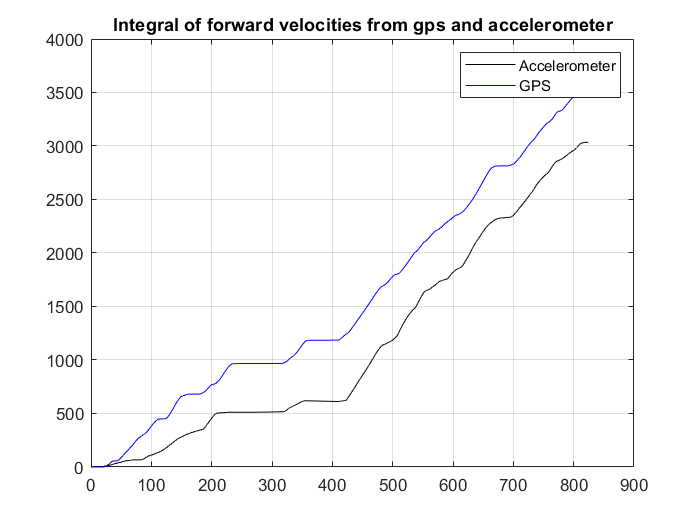

yaw_imu = imu_d.IMUorientationz;
x_obs = x_mod;
vel_obs = cumtrapz(time,x_obs);
disp_obs = cumtrapz(time,vel_obs);
disp_gps = cumtrapz(time_gps-time_gps(1),vel_gps);
plot(time-time(1),disp_obs,'k')
grid on
hold on
plot(time_gps-time_gps(1),disp_gps,'b')
title("Integral of forward velocities from gps and accelerometer")
legend("Accelerometer","GPS")
hold off

Dead Reckoning

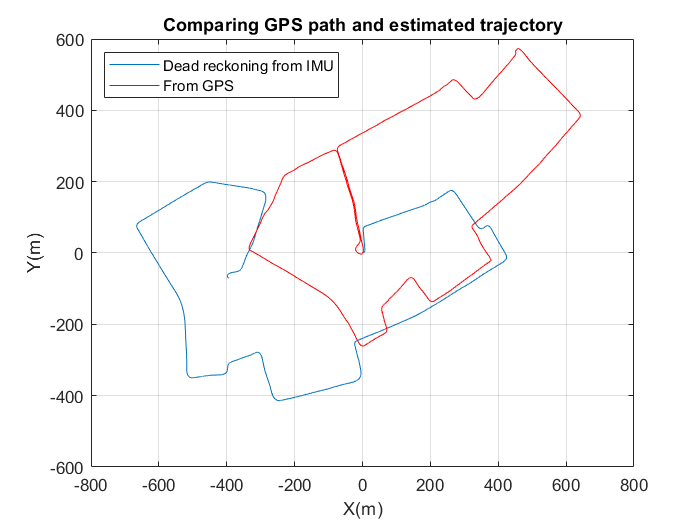

gps_e = gps.UTM_easting - gps.UTM_easting(1);
gps_n = gps.UTM_northing - gps.UTM_northing(1);
rot = unwrap(yaw_gyro);
v_e = -vel_mod.*cos(rot);
v_n = vel_mod.*sin(rot);
traj_e = cumtrapz(time,v_e);
traj_n = cumtrapz(time,v_n);
plot(traj_e,traj_n)
grid on
hold on
plot(gps_e,gps_n,'r')
title("Comparing GPS path and estimated trajectory")
legend("Dead reckoning from IMU","From GPS","Location","northwest")
xlabel('X(m)')
ylabel('Y(m)')
hold off

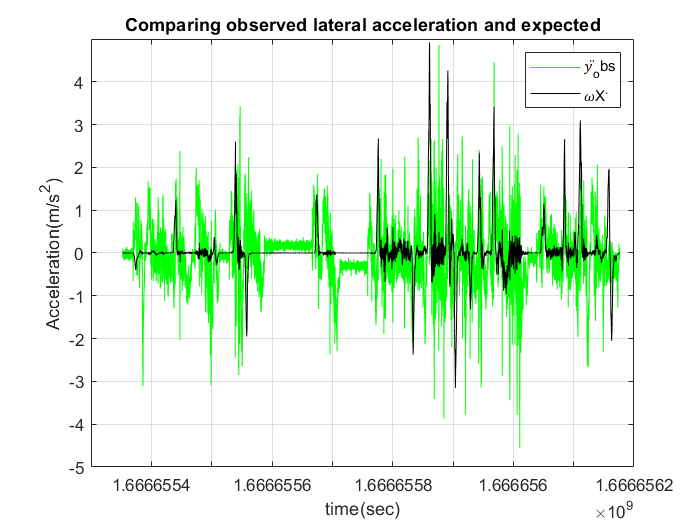

omegax = vel_mod.*rate_yaw;
plot(time,imu_d.IMUlinear_accelerationx,'g')
grid on
hold on
plot(time,omegax,'k')
title("Comparing observed lateral acceleration and expected")
legend("𝑦̈_obs","𝜔X^.")
xlabel('time(sec)')
ylabel('Acceleration(m/s^2)')
hold off